clear all
syms theta_ddot theta_dot theta y_ddot y_dot y l l_dot l_ddot F_y F_l

m_c = 50; 

sampler_radius = 0.05;
Cd = .3;
A = 4*pi*sampler_radius^2;
rho = 19300; 
V = 4/3*pi*sampler_radius^3;
m_s = rho*V; 
% m_c = 1;
% m_s = 1;
g = 9.81;
% r_c = [0 y 0];
% r_s = [0 y+l*sin(theta) -l*cos(theta)];
% 
% v_c = [0 y_dot 0];
% v_s = [0 y_dot+l_dot*sin(theta)+l*theta_dot*cos(theta) -l_dot*cos(theta)+l*theta_dot*sin(theta)];

eqn_y = F_y == (m_c+m_s)*y_ddot+m_s*(l_ddot*sin(theta)+2*l_dot*theta_dot*cos(theta)+l*theta_ddot*cos(theta)-l*theta_dot^2*sin(theta));
eqn_theta = 0 == m_s*(l^2*theta_ddot+2*l*l_dot*theta_dot+y_ddot*l*cos(theta)+g*l*sin(theta));
eqn_l = F_l == m_s*(l_ddot+y_ddot*sin(theta)-g*l*sin(theta)-l*theta_dot^2);


y_ddot0 = rhs(isolate(eqn_y, y_ddot)); % yddot in terms of theta_ddot and l_ddot
eqn_theta0 = subs(eqn_theta, y_ddot, y_ddot0); % eliminate y_ddot from theta eqn

theta_ddot0 = rhs(isolate(eqn_theta0, theta_ddot)); % theta_ddot in terms of l_ddot
eqn_l0 = subs(eqn_l, y_ddot, y_ddot0); % eliminate y_ddot from l eqn
eqn_l1 = subs(eqn_l0, theta_ddot, theta_ddot0); % eliminate theta_ddot from l eqn

l_ddot1 = rhs(isolate(eqn_l1, l_ddot)); % l_ddot in terms of state variables

l_ddot_simple = simplify(l_ddot1)

$$l\_ddot\_simple = \frac{5142726420376408031232\,\pi^{2}\,\cos\left(\theta \right)-5142726420376408031232\,\pi^{2}\,{\cos\left(\theta \right)}^{3}-562663453110976530000\,F_{l}-17755126594643419892415\,\pi \,l\,\sin\left(\theta \right)+162974011515469824000\,\pi \,F_{l}\,{\cos\left(\theta \right)}^{2}+524233070374761267200\,l\,{\dot{\theta }}^{2}\,\pi^{2}+162974011515469824000\,\pi \,F_{y}\,\sin\left(\theta \right)-1809900774173641171500\,\pi \,l\,{\dot{\theta }}^{2}+5142726420376408031232\,l\,\pi^{2}\,{\cos\left(\theta \right)}^{2}\,\sin\left(\theta \right)}{19300\,\pi \,\left(27162335252578304\,\pi -93777242185162755\right)}$$


eqn_theta1 = subs(eqn_theta0, l_ddot, l_ddot1);
theta_ddot1  = rhs(isolate(eqn_theta1, theta_ddot)); %theta_ddot in terms of state variables

theta_ddot_simple = simplify(theta_ddot1)

$$theta\_ddot\_simple = \frac{91995474583644662655\,\sin\left(\theta \right)+18755448437032551000\,\dot{l}\,\dot{\theta }+844424930131968000\,F_{y}\,\cos\left(\theta \right)-26646250882779316224\,\pi \,\sin\left(\theta \right)+26646250882779316224\,\pi \,l\,{\cos\left(\theta \right)}^{3}-844424930131968000\,F_{l}\,\cos\left(\theta \right)\,\sin\left(\theta \right)-5432467050515660800\,\pi \,\dot{l}\,\dot{\theta }+26646250882779316224\,\pi \,{\cos\left(\theta \right)}^{2}\,\sin\left(\theta \right)-26646250882779316224\,\pi \,l\,\cos\left(\theta \right)}{100\,l\,\left(27162335252578304\,\pi -93777242185162755\right)}$$


eqn_yddot0 = subs(eqn_y, theta_ddot, theta_ddot1); 
eqn_yddot1 = subs(eqn_yddot0, l_ddot, l_ddot1);

y_ddot_simple = simplify(rhs(isolate(eqn_yddot1, y_ddot)))

$$y\_ddot\_simple = -\frac{105553116266496\,\left(63111\,l\,\pi \,{\cos\left(\theta \right)}^{2}+63111\,\pi \,\sin\left(\theta \right)\,\cos\left(\theta \right)+2000\,F_{y}-63111\,\pi \,l-2000\,F_{l}\,\sin\left(\theta \right)\right)}{25\,\left(27162335252578304\,\pi -93777242185162755\right)}$$

y_ddot = y_ddot_simple;
l_ddot = l_ddot_simple;
theta_ddot = theta_ddot_simple;


X = [y; y_dot; theta; theta_dot; l; l_dot];
X_dot = [y_dot; y_ddot; theta_dot; theta_ddot; l_dot; l_ddot];

A = sym(nan(length(X_dot), length(X)));

for i = 1:length(X)
    A(:,i) = diff(X_dot, X(i));
end

%disp(A)
X_eqbm = [0, 0, 0, 0, 1,0]';
F = [F_y; F_l];
F_eqbm = [0; 0];


A_lin = double(subs(A, [X; F], [X_eqbm; F_eqbm]));
%disp(A_lin)



B = sym(nan(length(X_dot), length(F)));
for j = 1:length(F)
    B(:,j) = diff(X_dot, F(j));
end


B_lin = double(subs(B, X, X_eqbm));
disp(B_lin)

         0         0
    1.0000         0
         0         0
   -1.0000         0
         0         0
         0    0.0990




% m_c = 1;
% m_s = 1;

Q =[1000  0  0      0    0   0;
    0    10  0      0   0    0;
    0     0  1000   0   0    0;
    0     0  0      10  0    0;
    0     0  0      0   100000 0;
    0     0  0      0    0   100000];

R = .001;

K = lqr(A_lin, B_lin, Q, R);

D = 0;
C = [1 0 0 0 0 0;
     0 0 1 0 0 0
     0 0 0 0 1 0];
 
U = [F_y; F_l];

% assess controllability
states = {'y' 'y_dot' 'theta' 'theta_dot' 'l' 'l_dot'};
inputs = {'f_y, f_l'};
outputs = {'y'; 'theta';'l'};

sys_ss = ss(A_lin,B_lin,C,D,'statename',states,'inputname',inputs,'outputname',outputs);

poles = eig(A_lin); %% poles without Control
co = ctrb(sys_ss);
controllability = rank(co);




Ac = (A_lin-B_lin*K);
Bc = B_lin;
Cc = C;
Dc = D;

poles1 = eig(Ac); %% poles with LQR
states = {'y' 'y_dot' 'phi1' 'phi_dot1' 'l' 'l_dot'};
inputs = {'f_y'};
outputs = {'y'; 'phi1'; 'l'};

sys_cl = ss(Ac,Bc,Cc,Dc,'statename',states,'inputname',inputs,'outputname',outputs);



% hold on
x0=[2,0,pi/6,0,1,0];  %% initial condition
t = 0:0.1:100;
r =8*zeros(length(t),2); %% Step input 
[y,t,x]=lsim(sys_cl,r,t,x0); %% simulation command
% figure
% [AX,H1,H2] = plotyy(t,y(:,1),t,y(:,2),'plot'); %% Plot of x and Theta 1
% set(get(AX(1),'Ylabel'),'String','cart position (m)')
% set(get(AX(2),'Ylabel'),'String','pendulum 1 angle (radians)')
%  figure %% new figure
%  
% [AX,H1,H3] = plotyy(t,y(:,1),t,y(:,3),'plot');  %% Plot of x and Theta 2
% set(get(AX(1),'Ylabel'),'String','cart position (m)')
% set(get(AX(2),'Ylabel'),'String','pendulum 2 angle (radians)')
% title('Step Response with LQR Control')


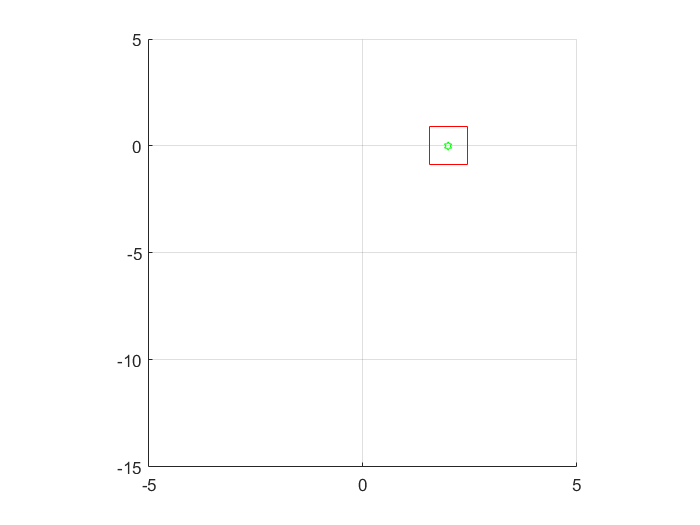

y = x(:,1);
theta = x(:,3);
l = x(:,5);
pend1y=-l.*sin(theta)+y;
pend1z=-l.*cos(theta);
figure(1);
clf
hold on;
axis([-5 5 -15 5]);
axis('square');
grid on;


hbead=line(y(1),t(1),'color','r','marker','square','markersize',30);

line1y=[y,pend1y];
line1z=[zeros(length(t),1),pend1z];
hbead1=line(line1y(1),line1z(1),'marker','hexagram','markersize',5,'color','g');

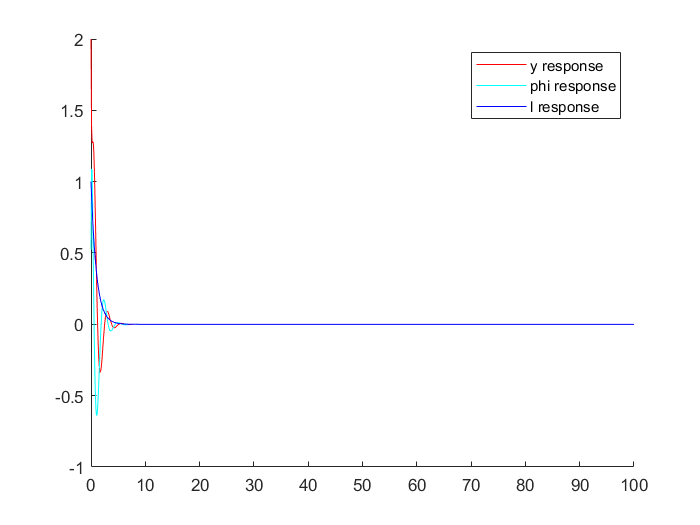



% for k=2:length(t)
% set(hbead,'xdata',x(k,1),'ydata',0);
% set(hbead1,'xdata',line1y(k,:),'ydata',line1z(k,:));
% drawnow
% % F(k)=getframe(gcf);
% end

figure;
hold on
plot(t,x(:,1),'r')
plot(t,x(:,3),'c')
plot(t,x(:,5),'b')
legend('y response','phi response','l response')